# Documento para crear una mapa apartir de una imagen

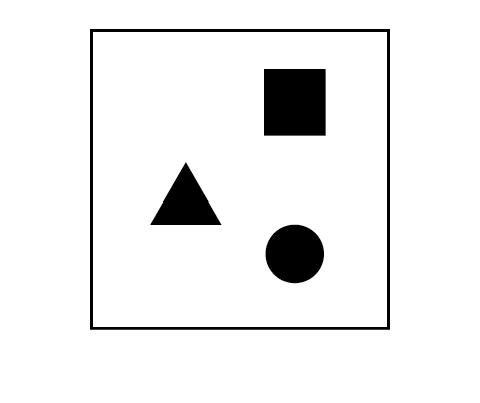

% 1. Primero se crea una png, bmp



imagecrop = imread('mapa2.png', 'png');
imshow(imagecrop)

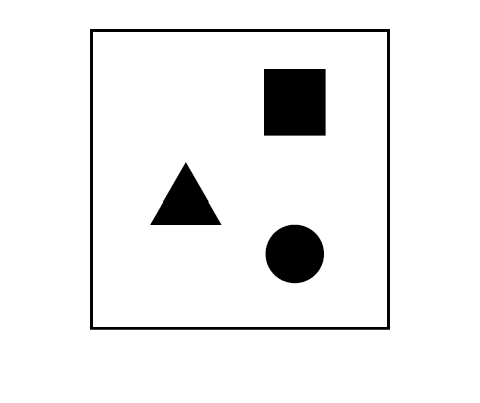

imagecrop = imagecrop(:,:,1); % Se toma la capa 1
imshow(imagecrop);

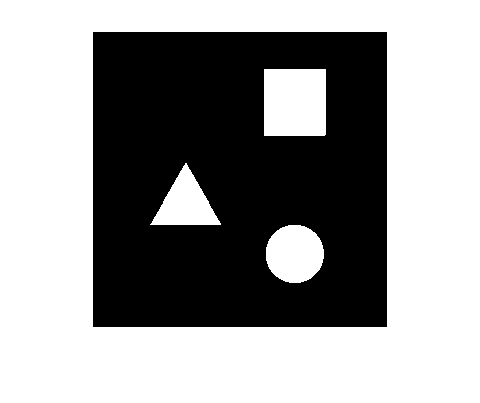

% Depuracion
% Los obstaculos,  ahora son 1 ocupados y espacio libre 0
% en la imagen 1 es blanco y cero negro.

Xd = imagecrop<128;
imshow(Xd);


% Se crea un mapa ajustando la resolucion y dando dimensiones a los pixel
% de 300 x 300 pixel. se convierte con uns resolucio de 50/m 50pixel/m.

map2 = binaryOccupancyMap(Xd,50) % Crea el mapa con resolucion de 50

map2 =   binaryOccupancyMap with properties:

   mapLayer Properties
              LayerName: 'binaryLayer'
               DataType: 'logical'
           DefaultValue: 0
    GridLocationInWorld: [0 0]
      GridOriginInLocal: [0 0]
     LocalOriginInWorld: [0 0]
             Resolution: 50
               GridSize: [300 300]
           XLocalLimits: [0 6]
           YLocalLimits: [0 6]
           XWorldLimits: [0 6]
           YWorldLimits: [0 6]


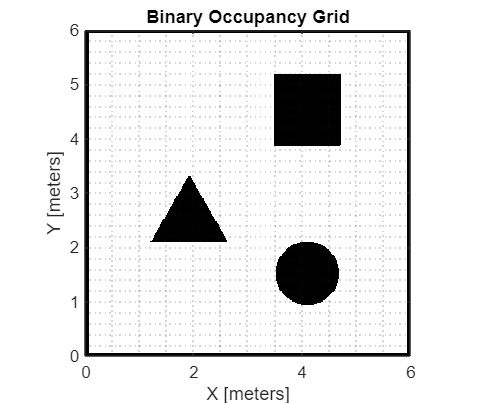

show(map2)                       % Celdas por metro, cada celda un pixel
grid  minor                            % En total son 3 mts.

## Convertir Pgm (Portable grey Maps)

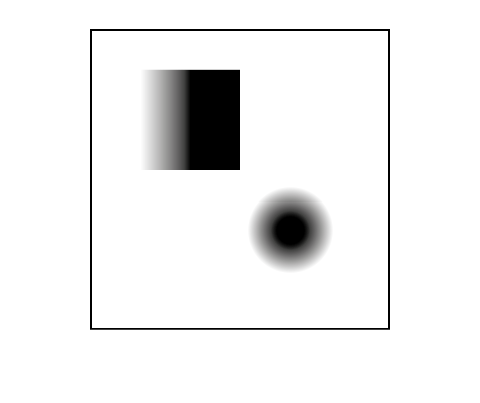

clear

image = imread('mapa3.png','png');
imshow(image)

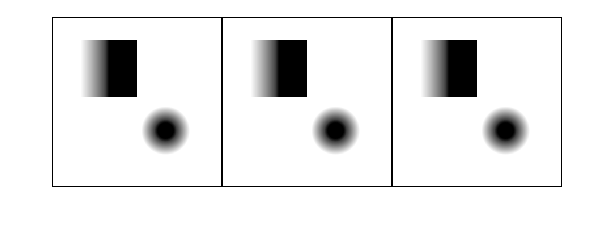

imagecrop = image(:,:);
% imagecrop = image(1:300,1:300); % Croop de la imagen
imshow(imagecrop);

% los valores se expresan de 0 a 255 como uint8.
% Normalice estos valores convirtiendo la imagen recortada al doble y
% dividiendo cada celda por 255
imageNorm = double(imagecrop)/255;
imageOccupancy = 1 - imageNorm; % Reste la imagen normalizada de 1 para obtener los valores de ocupación con
% 1 que representa el espacio ocupado

% image = image<128;

map3 = occupancyMap(imageOccupancy,50) % Crea el mapa con resolucion de 50

map3 =   occupancyMap with properties:

   mapLayer Properties
        OccupiedThreshold: 0.6500
            FreeThreshold: 0.2000
    ProbabilitySaturation: [0.0010 0.9990]
                LayerName: 'probabilityLayer'
                 DataType: 'double'
             DefaultValue: 0.5000
      GridLocationInWorld: [0 0]
        GridOriginInLocal: [0 0]
       LocalOriginInWorld: [0 0]
               Resolution: 50
                 GridSize: [300 900]
             XLocalLimits: [0 18]
             YLocalLimits: [0 6]
             XWorldLimits: [0 18]
             YWorldLimits: [0 6]


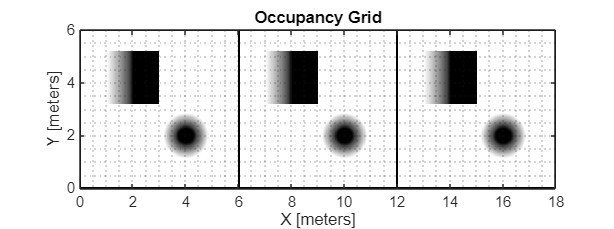

show(map3)                       % Celdas por metro, cada celda un pixel
grid  minor

## Indicar la probalidad de ocupacion de l celda

obj1 = getOccupancy(map3, [200, 200], "grid")

obj1 = 0.9990

obj2 = getOccupancy(map3, [170, 200], "grid")

obj2 = 0.3843

obj3 = getOccupancy(map3, [150, 200], "grid")

obj3 = 0.0010